### Imports

addpath("/d/gmi/1/simeon/simul_scalp/fieldtrip")
addpath("/d/gmi/1/simeon/simul_scalp/fieldtrip/external/spm12")
addpath("/d/gmi/1/simeon/hsc-eeg-tools/MATLAB")
ft_defaults

### Load headmodel

clear
load fieldtrip/template/headmodel/standard_seg.mat

### Generate hexahedral mesh

cfg        = [];
cfg.shift  = 0.3;
cfg.method = 'hexahedral';
cfg.datatype = 'indexed';
hex_mesh = ft_prepare_mesh(cfg, mri);

 In fixsegmentation at line 20
 In ft_datatype_segmentation at line 173
 In ft_checkdata at line 285
 In prepare_mesh_hexahedral at line 18
 In ft_prepare_mesh at line 170

using the field "seg" with the segmented tissue types tissue 1, tissue 2 and tissue 3
Created elements...
Created nodes...
Applying shift 0.300000
the call to "ft_prepare_mesh" took 12 seconds and required the additional allocation of an estimated 0 MB


% fill in missing labels
hex_mesh.tissuelabel = {'scalp', 'skull', 'brain'};

### Load scalp and SEEP electrode locations

% load 10-20 electrodes
elec = ft_read_sens('standard_1020.elc');

### **Poke a hole at Cz**

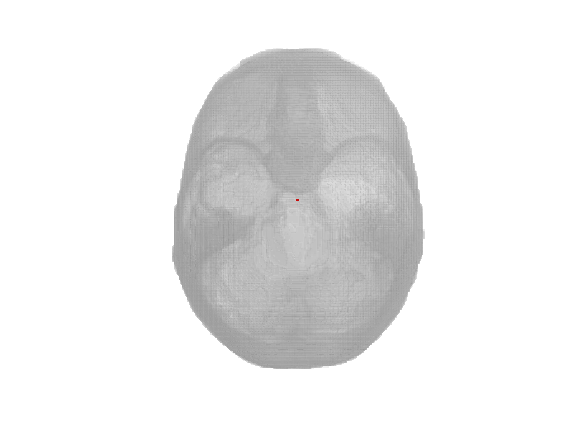

BURRHOLE_SIZE = 1.5;

cz_pos = elec.chanpos(strcmp(elec.label, 'Cz'), :);
line_slope = [0 0 -1];

hex_mesh_holey = hex_mesh;
skull_idx = find(strcmp(hex_mesh.tissuelabel, 'skull'));
scalp_idx = find(strcmp(hex_mesh.tissuelabel, 'scalp'));
skh = find(hex_mesh.tissue == skull_idx | hex_mesh.tissue == scalp_idx);  % skull hexes
for kk = 1:length(skh)
    hex_pos = mean(hex_mesh.pos(hex_mesh.hex(skh(kk), :), :), 1);
    b = cz_pos - hex_pos;
    distance_to_line = norm(cross(line_slope, b)) / norm(line_slope);
    distance_to_point = norm(b);

    if distance_to_line < (BURRHOLE_SIZE / 2) && distance_to_point < 50
        hex_mesh_holey.tissue(skh(kk)) = 4;
    end
end

% plotting
figure;
sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == skull_idx, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', [0.8 0.8 0.8], ...
    'facealpha', 0.1);
hold on
sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == 4, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', '#FF0000', ...
    'facealpha', 1);
view([0, 90])
camlight

hex_mesh_holey.tissuelabel{4} = 'holes';

### **Add simulated electrodes anteriorly at 1mm spacing**

scalp_idx = find(strcmp(hex_mesh.tissuelabel, 'scalp'));
indices = find(hex_mesh.tissue == scalp_idx);


% get closest scalp hex position
[hex_dist, hex_pos] = get_distance_to_point(hex_mesh, indices, cz_pos);

[~, min_idx] = min(hex_dist);
current_position = hex_pos(min_idx, :);

n_steps = 100;
step_size = 1;
sim_positions = [];


for kk = 1:n_steps
    % find all hex positions within 1mm of the current position
    [hex_dist, hex_pos] = get_distance_to_point(hex_mesh, indices, current_position);

    % select the most anterior of the positions
    within_dist = find(hex_dist <= step_size);
    hex_pos_sel = hex_pos(within_dist, :);
    
    [most_anterior_y, most_anterior_idx] = max(hex_pos_sel(:,2));
    most_anterior_idx = within_dist(most_anterior_idx);

    new_pos = hex_pos(most_anterior_idx, :);

    % repeat
    sim_positions = [sim_positions; new_pos;];

    current_position = new_pos;
end

sim_positions = sim_positions + [0, 0, 1];


Plotting

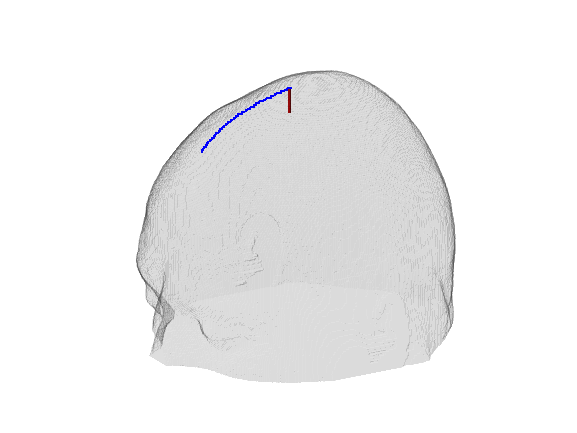

sim_sens = [];
sim_sens.label = arrayfun(@(x) sprintf('%.0fmm', x), step_size * (1:n_steps), UniformOutput=false);
sim_sens.chanpos = sim_positions;
sim_sens.elecpos = sim_sens.chanpos;
sim_sens.unit = 'mm';
sim_sens.chantype = repmat({'eeg'}, size(sim_positions, 1), 1);

figure;
hold on
ft_plot_mesh(hex_mesh, ...
    'surfaceonly','yes',...
    'vertexcolor','none',...
    'edgecolor','none',...
    'facecolor',[0.5 0.5 0.5],...
    'facealpha',0.1)
camlight
ft_plot_sens(sim_sens, 'style', 'b',...
    'elec', true, ...
    'elecsize', 5);

sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == 4, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', '#FF0000', ...
    'facealpha', 1);
view([-120, 20]);
exportgraphics(gcf, 'scalpeeg_elecbydistance+1z.png', 'Resolution', 600)

### Generate headmodels

conductivities = struct('gray', 0.33, 'white', 0.14, 'csf', 1.79, 'brain', 1.5, 'skull', 0.01, 'scalp', 0.43, 'holes', 1.79);  % check brain
cfg        = [];
cfg.method = 'simbio';
cfg.conductivity = cellfun(@(x) conductivities.(x), hex_mesh.tissuelabel);

headmodel_orig  = ft_prepare_headmodel(cfg, hex_mesh);

the call to "ft_prepare_headmodel" took 108 seconds and required the additional allocation of an estimated 859 MB



cfg.conductivity = cellfun(@(x) conductivities.(x), hex_mesh_holey.tissuelabel);
headmodel_hole  = ft_prepare_headmodel(cfg, hex_mesh_holey);

the call to "ft_prepare_headmodel" took 106 seconds and required the additional allocation of an estimated 860 MB


save('headmodels_elecbydistance+1z.mat', 'headmodel_orig', 'headmodel_hole');

cfg = [];
cfg.elec = sim_sens;
cfg.resolution = 5;

cfg.headmodel = headmodel_orig;
sourcemodel_orig = ft_prepare_leadfield(cfg);

using electrodes specified in the configuration
Find electrode positions...
Calculate transfer matrix...
Electrode 2 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 0

Electrode 3 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8788e-09

Electrode 4 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9346e-09

Electrode 5 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9708e-09

Electrode 6 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5731e-09

Electrode 7 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9941e-09

Electrode 8 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2575e-09

Electrode 9 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8223e-09

Electrode 10 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2605e-09

Electrode 11 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1115e-09

Electrode 12 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1536e-09

Electrode 13 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8938e-09

Electrode 14 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3405e-09

Electrode 15 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8617e-09

Electrode 16 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9821e-09

Electrode 17 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1611e-09

Electrode 18 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1654e-09

Electrode 19 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8694e-09

Electrode 20 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9799e-09

Electrode 21 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0991e-09

Electrode 22 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3170e-09

Electrode 23 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3505e-09

Electrode 24 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2496e-09

Electrode 25 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2764e-09

Electrode 26 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7423e-09

Electrode 27 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7448e-09

Electrode 28 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5628e-09

Electrode 29 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5363e-09

Electrode 30 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3409e-09

Electrode 31 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7948e-09

Electrode 32 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5194e-09

Electrode 33 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0838e-09

Electrode 34 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3559e-09

Electrode 35 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5314e-09

Electrode 36 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4684e-09

Electrode 37 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3812e-09

Electrode 38 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9599e-09

Electrode 39 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2999e-09

Electrode 40 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8865e-09

Electrode 41 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3374e-09

Electrode 42 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1605e-09

Electrode 43 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9036e-09

Electrode 44 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7265e-09

Electrode 45 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9777e-09

Electrode 46 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5553e-09

Electrode 47 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1029e-09

Electrode 48 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1288e-09

Electrode 49 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4982e-09

Electrode 50 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6336e-09

Electrode 51 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3642e-09

Electrode 52 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5006e-09

Electrode 53 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4766e-09

Electrode 54 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4766e-09

Electrode 55 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1933e-09

Electrode 56 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1675e-09

Electrode 57 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8309e-09

Electrode 58 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5849e-09

Electrode 59 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1689e-09

Electrode 60 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8641e-09

Electrode 61 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9419e-09

Electrode 62 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3352e-09

Electrode 63 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8286e-09

Electrode 64 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7866e-09

Electrode 65 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4817e-09

Electrode 66 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2282e-09

Electrode 67 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8481e-09

Electrode 68 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4817e-09

Electrode 69 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5561e-09

Electrode 70 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8889e-09

Electrode 71 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9170e-09

Electrode 72 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8047e-09

Electrode 73 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6726e-09

Electrode 74 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4438e-09

Electrode 75 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5845e-09

Electrode 76 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8646e-09

Electrode 77 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6480e-09

Electrode 78 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6603e-09

Electrode 79 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4506e-09

Electrode 80 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5639e-09

Electrode 81 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8052e-09

Electrode 82 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6419e-09

Electrode 83 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2429e-09

Electrode 84 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7598e-09

Electrode 85 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5431e-09

Electrode 86 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5208e-09

Electrode 87 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2371e-09

Electrode 88 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2681e-09

Electrode 89 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4518e-09

Electrode 90 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4624e-09

Electrode 91 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5433e-09

Electrode 92 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5092e-09

Electrode 93 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5092e-09

Electrode 94 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6677e-09

Electrode 95 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1139e-09

Electrode 96 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2054e-09

Electrode 97 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9833e-09

Electrode 98 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9386e-09

Electrode 99 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8711e-09

Electrode 100 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8201e-09

creating sourcemodel based on automatic 3D grid with specified resolution
using electrodes specified in the configuration
creating 3D grid with 5 mm resolution
initial 3D grid dimensions are [41 49 41]
selecting dipole positions inside the 'brain' tissue
pruning headmodel volume elements from 3988702 to 2047902 (51%)
pruning headmodel vertices from 4080232 to 2113968 (52%)
pruning dipole positions from 82369 to 32190 (39%)
16421 dipoles inside, 65948 dipoles outside brain
making tight grid
16421 dipoles inside, 15769 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 10 seconds and required the additional allocation of an estimated 4310 MB
computing leadfield
computing leadfield 16421/16421

the call to "ft_prepare_leadfield" took 15992 seconds and required the additional allocation of an estimated 7374 MB



cfg.headmodel = headmodel_hole;
sourcemodel_hole = ft_prepare_leadfield(cfg);

using electrodes specified in the configuration
Find electrode positions...
Calculate transfer matrix...
Electrode 2 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 0

Electrode 3 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5386e-09

Electrode 4 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5070e-09

Electrode 5 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1968e-09

Electrode 6 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9114e-09

Electrode 7 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3504e-09

Electrode 8 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5672e-09

Electrode 9 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4739e-09

Electrode 10 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7031e-09

Electrode 11 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7878e-09

Electrode 12 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3921e-09

Electrode 13 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4443e-09

Electrode 14 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7493e-09

Electrode 15 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1207e-09

Electrode 16 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2532e-09

Electrode 17 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7074e-09

Electrode 18 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6225e-09

Electrode 19 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5146e-09

Electrode 20 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3808e-09

Electrode 21 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8123e-09

Electrode 22 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6734e-09

Electrode 23 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6897e-09

Electrode 24 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5277e-09

Electrode 25 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6633e-09

Electrode 26 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.5601e-09

Electrode 27 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.7678e-09

Electrode 28 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9916e-09

Electrode 29 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9327e-09

Electrode 30 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7531e-09

Electrode 31 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0986e-09

Electrode 32 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8850e-09

Electrode 33 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1132e-09

Electrode 34 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4381e-09

Electrode 35 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4863e-09

Electrode 36 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6067e-09

Electrode 37 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6167e-09

Electrode 38 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1015e-09

Electrode 39 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2818e-09

Electrode 40 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9705e-09

Electrode 41 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2371e-09

Electrode 42 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3459e-09

Electrode 43 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7258e-09

Electrode 44 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6464e-09

Electrode 45 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1253e-09

Electrode 46 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8763e-09

Electrode 47 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1983e-09

Electrode 48 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1570e-09

Electrode 49 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5932e-09

Electrode 50 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7994e-09

Electrode 51 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6714e-09

Electrode 52 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5593e-09

Electrode 53 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7403e-09

Electrode 54 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7403e-09

Electrode 55 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7976e-09

Electrode 56 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1182e-09

Electrode 57 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7268e-09

Electrode 58 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7439e-09

Electrode 59 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0907e-09

Electrode 60 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8793e-09

Electrode 61 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8814e-09

Electrode 62 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1519e-09

Electrode 63 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.7829e-09

Electrode 64 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6956e-09

Electrode 65 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2983e-09

Electrode 66 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0919e-09

Electrode 67 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8928e-09

Electrode 68 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3627e-09

Electrode 69 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5530e-09

Electrode 70 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8058e-09

Electrode 71 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9569e-09

Electrode 72 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0545e-09

Electrode 73 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6323e-09

Electrode 74 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3783e-09

Electrode 75 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3845e-09

Electrode 76 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5200e-09

Electrode 77 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5070e-09

Electrode 78 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4918e-09

Electrode 79 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3474e-09

Electrode 80 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5473e-09

Electrode 81 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7433e-09

Electrode 82 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6686e-09

Electrode 83 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1594e-09

Electrode 84 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5081e-09

Electrode 85 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5054e-09

Electrode 86 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4859e-09

Electrode 87 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3296e-09

Electrode 88 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3910e-09

Electrode 89 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4660e-09

Electrode 90 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5573e-09

Electrode 91 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6986e-09

Electrode 92 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7269e-09

Electrode 93 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7269e-09

Electrode 94 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4225e-09

Electrode 95 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3128e-09

Electrode 96 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2389e-09

Electrode 97 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1232e-09

Electrode 98 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9640e-09

Electrode 99 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9886e-09

Electrode 100 of 100
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0762e-09

creating sourcemodel based on automatic 3D grid with specified resolution
using electrodes specified in the configuration
creating 3D grid with 5 mm resolution
initial 3D grid dimensions are [41 49 41]
selecting dipole positions inside the 'brain' tissue
pruning headmodel volume elements from 3988702 to 2047902 (51%)
pruning headmodel vertices from 4080232 to 2113968 (52%)
pruning dipole positions from 82369 to 32190 (39%)
16421 dipoles inside, 65948 dipoles outside brain
making tight grid
16421 dipoles inside, 15769 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 10 seconds and required the additional allocation of an estimated 4311 MB
computing leadfield
computing leadfield 16421/16421

the call to "ft_prepare_leadfield" took 15986 seconds and required the additional allocation of an estimated 4310 MB



save('sourcemodels_elecbydistance+1z.mat', 'sourcemodel_hole', 'sourcemodel_orig');

### Leadfield differences

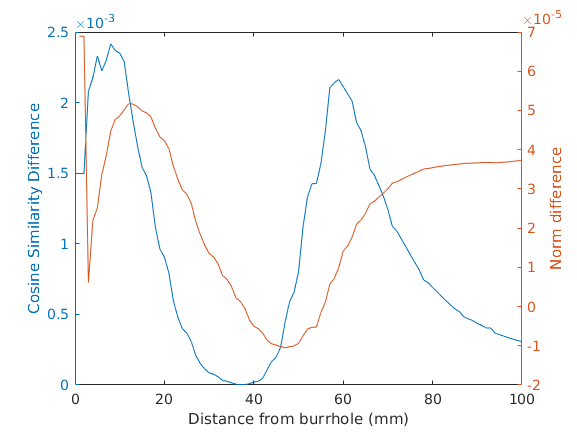

dhole = cellfun(@(x) ~isempty(x), sourcemodel_hole.leadfield);
dorig = cellfun(@(x) ~isempty(x), sourcemodel_orig.leadfield);

dcommon = dhole & dorig;
dcommon = find(dcommon);

lf_orig = cat(3, sourcemodel_orig.leadfield{dcommon});
lf_hole = cat(3, sourcemodel_hole.leadfield{dcommon});

cos_diff = zeros(length(sourcemodel_orig.label), 1);
for kk = 1:length(sourcemodel_orig.label)
    lfo = squeeze(rssq(lf_orig(kk,:,:),2));
    lfh = squeeze(rssq(lf_hole(kk,:,:),2));

    cos_diff(kk) = abs(1 - (dot(lfo(:), lfh(:)) / (norm(lfo(:)) * norm(lfh(:)))));
end

norm_diff = zeros(length(sourcemodel_orig.label), 1);
for kk = 1:length(sourcemodel_orig.label)
    lfo = squeeze(rssq(lf_orig(kk,:,:),2));
    lfh = squeeze(rssq(lf_hole(kk,:,:),2));

    norm_diff(kk) = rssq(lfo(:)) - rssq(lfh(:));
end

figure
yyaxis left
plot(cos_diff)
ylabel('Cosine Similarity Difference')
yyaxis right
plot(norm_diff)
ylabel('Norm difference')

xlabel('Distance from burrhole (mm)')

exportgraphics(gcf, 'differences_by_distance+1z.pdf', 'BackgroundColor', 'none')

function [hex_dist, hex_pos] = get_distance_to_point(hex_mesh, indices, target)
hex_dist = zeros(length(indices), 1);
hex_pos = zeros(length(indices), 3);
for kk = 1:length(indices)
    hex_pos(kk,:) = mean(hex_mesh.pos(hex_mesh.hex(indices(kk), :), :), 1);
    hex_dist(kk) = norm(hex_pos(kk,:) - target);
end
end

function get_distance_to_line(hex_mesh, indices, line_point, line_slope)
distance_to_line = zeros(length(indices), 1);
distance_to_point = zeros(length(indices), 1);
for kk = 1:length(indices)
    hex_pos = mean(hex_mesh.pos(hex_mesh.hex(skh(kk), :), :), 1);
    b = line_point - hex_pos;
    distance_to_line(kk) = norm(cross(line_slope, b)) / norm(line_slope);
    distance_to_point(kk) = norm(b);
end
end